%% PROJECT 1: BASIC KINEMATIC & RACING LINE OPTIMIZATION
% Model: Point Mass, Beta=0, No Complex Aero, Constant Grip.
% Objective: Compare "Centerline" vs. "Optimized Racing Line".

clear; close all; clc;

%% 1. PARAMETERS (CONSTANTS)
% ---------------------------------------------------------
filename = fullfile(pwd, 'Circuits_Data', 'de-1927.geojson'); % Your file
ds = 2.0;               % Discretization step (m)
track_width = 12.0;     % Track width (m)

% Vehicle (Simplified)
m = 750;                % Mass (kg)
P_max = 735500;         % Power (W)
F_max = 180000;          % Max Traction Force (N)
F_brake = 42000;        % Max Braking Force (N)
mu = 2.7;               % Friction Coefficient (Constant!)
g = 9.81;
v_max_abs = 330 / 3.6;  % Absolute max speed (m/s)

%% 2. TRACK LOADING & PREPARATION
% ---------------------------------------------------------
try
    jsonText = fileread(filename); data = jsondecode(jsonText);
    if isfield(data,'features'), raw=data.features(1).geometry.coordinates; else, raw=data.geometry.coordinates; end
    lon=raw(:,1); lat=raw(:,2);
catch
    error('File not found. Check the path.');
end

% GPS -> Meters Conversion (Track Centerline)
R_earth=6371000; lat0=lat(1); lon0=lon(1);
x_center = R_earth*deg2rad(lon-lon0)*cos(deg2rad(lat0));
y_center = R_earth*deg2rad(lat-lat0);

% Clean duplicates
d2=diff(x_center).^2+diff(y_center).^2; is_mov=[true; d2>1e-5];
x_center=x_center(is_mov); y_center=y_center(is_mov);

% Close the loop
if norm([x_center(1)-x_center(end), y_center(1)-y_center(end)]) > 5
    x_center(end+1)=x_center(1); y_center(end+1)=y_center(1);
end

% Splines for regular spacing on Centerline
dist_s = sqrt(diff(x_center).^2+diff(y_center).^2); t_raw=[0; cumsum(dist_s)];
pp_x = spline(t_raw, x_center); pp_y = spline(t_raw, y_center);
S_final = 0:ds:t_raw(end);
x_center = ppval(pp_x, S_final); y_center = ppval(pp_y, S_final);

%% 3. TRAJECTORY OPTIMIZATION (RACING LINE)
% ---------------------------------------------------------
% We create a second line "x_opt, y_opt" by deforming the first one.
fprintf('Optimizing Trajectory (Racing Line)...\n');

Optimizing Trajectory (Racing Line)...



x_opt = x_center; 
y_opt = y_center;
N = length(x_opt);
iterations = 100; % Pull the "rubber band" 100 times
alpha = 0.5;      % Smoothing factor (Elasticity)

for k = 1:iterations
    for i = 2:N-1
        % Midpoint (Chord of the turn)
        xm = (x_opt(i-1) + x_opt(i+1)) / 2;
        ym = (y_opt(i-1) + y_opt(i+1)) / 2;
        
        % Move current point towards the chord (Apex cutting)
        xn = (1-alpha)*x_opt(i) + alpha*xm;
        yn = (1-alpha)*y_opt(i) + alpha*ym;
        
        % CONSTRAINT: Must stay within track boundaries
        % Calculate distance from the FIXED Centerline
        dist = sqrt((xn - x_center(i))^2 + (yn - y_center(i))^2);
        limit = track_width / 2;
        
        if dist < limit
            x_opt(i) = xn; y_opt(i) = yn;
        else
            % Project back onto the track edge
            ratio = limit / dist;
            x_opt(i) = x_center(i) + (xn - x_center(i)) * ratio;
            y_opt(i) = y_center(i) + (yn - y_center(i)) * ratio;
        end
    end
    % Close loop
    x_opt(1)=x_opt(N); y_opt(1)=y_opt(N);
end

%% 4. SPEED PROFILE CALCULATION (Function call)
% We run the physics engine twice: once for Center, once for Opt
[v_center, T_center] = Compute_Speed_Profile(x_center, y_center, ds, m, P_max, F_max, F_brake, mu, g, v_max_abs);
[v_opt, T_opt]       = Compute_Speed_Profile(x_opt, y_opt, ds, m, P_max, F_max, F_brake, mu, g, v_max_abs);

%% 5. VISUALISATION DÉTAILLÉE (ZOOM SUR VIRAGE)
% ---------------------------------------------------------
fprintf('\n--- RÉSULTATS ---\n');


--- RÉSULTATS ---


fprintf('Temps Centerline  : %.2f s\n', T_center);

Temps Centerline  : 90.96 s


fprintf('Temps Racing Line : %.2f s\n', T_opt);

Temps Racing Line : 87.70 s


fprintf('GAIN              : -%.2f s\n', T_center - T_opt);

GAIN              : -3.26 s


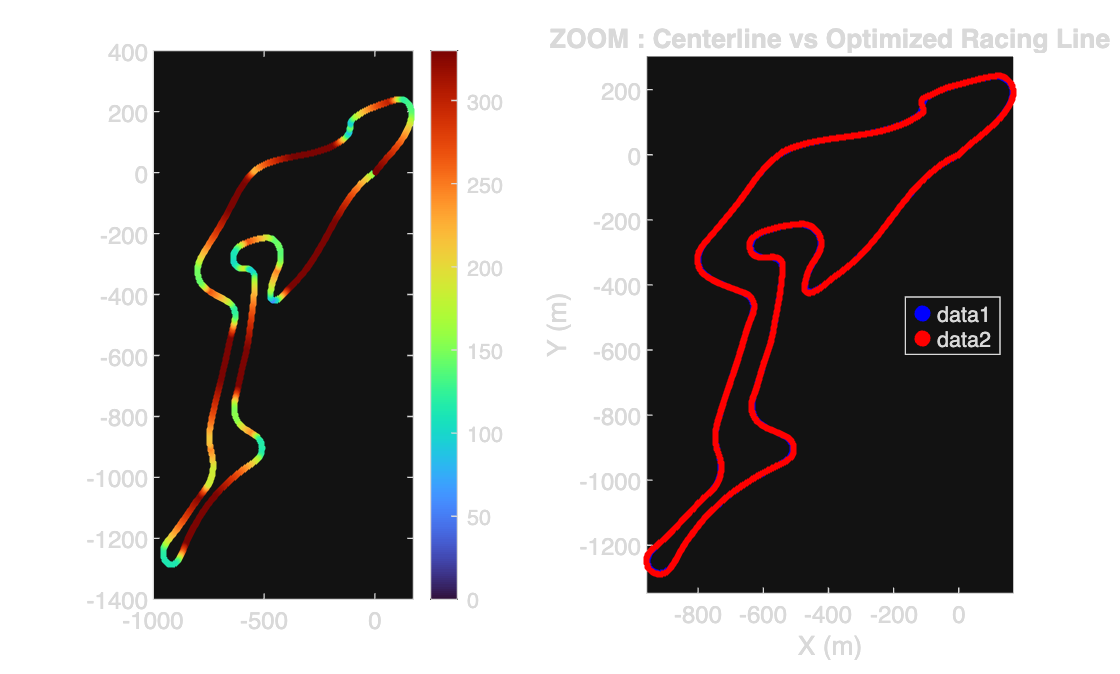


% 1. Calcul des bords de la piste pour l'affichage
% Vecteur Normal à la piste
dx = gradient(x_center); 
dy = gradient(y_center);
norms = sqrt(dx.^2 + dy.^2);
nx = -dy ./ norms; % Normale X
ny = dx ./ norms;  % Normale Y

% Bords Gauche et Droite
w = track_width / 2;
x_in = x_center + nx * w; y_in = y_center + ny * w;
x_out = x_center - nx * w; y_out = y_center - ny * w;

% --- FIGURE 1 : VUE GLOBALE ---
figure('Name', 'Global View', 'Color', 'w');
subplot(1,2,1)
plot(x_in, y_in, 'k-', 'LineWidth', 0.1); hold on; % Bord Int
plot(x_out, y_out, 'k-', 'LineWidth', 0.1); % Bord Ext
% On affiche la trajectoire optimisée en couleur
scatter(x_opt, y_opt, 5, v_opt*3.6, 'filled');
colormap turbo; colorbar;

subplot(1,2,2)

scatter(x_opt, y_opt, 5, 'b', 'filled');
hold('on')
scatter(x_center, y_center, 5, 'r', 'filled');
legend("Location","best")
axis equal;


% Esthétique
legend('Location', 'Best');
axis equal;
title('ZOOM : Centerline vs Optimized Racing Line');
xlabel('X (m)'); ylabel('Y (m)');


% Calcul de l'écart max pour confirmer mathématiquement
dev = sqrt((x_opt - x_center).^2 + (y_opt - y_center).^2);
fprintf('Déviation Max par rapport au centre : %.2f mètres (Limite: %.1f m)\n', max(dev), track_width/2);

Déviation Max par rapport au centre : 6.00 mètres (Limite: 6.0 m)




%% ==========================================================
%% PHYSICS ENGINE (FORWARD-BACKWARD ALGORITHM)
%% ==========================================================
function [v_final, T_total] = Compute_Speed_Profile(x, y, ds, m, P_max, F_max, F_brake, mu, g, v_top)
    
    % 1. Compute Curvature
    n = length(x);
    dx = gradient(x, ds); dy = gradient(y, ds);
    ddx = gradient(dx, ds); ddy = gradient(dy, ds);
    % Curvature Formula k = (x'y'' - y'x'') / (x'^2 + y'^2)^1.5
    k = abs((dx.*ddy - dy.*ddx) ./ (dx.^2 + dy.^2).^(1.5));
    k(isnan(k)) = 0;

    % 2. Static Limit (Cornering Speed)
    % Condition: Centrifugal Force <= Friction Force
    % m*v^2 * k <= mu * m * g  => v <= sqrt(mu*g / k)
    v_limit = sqrt((mu * g) ./ (k + 1e-6));
    v_limit = min(v_limit, v_top);

    % 3. Forward Pass (Max Acceleration)
    v_fwd = zeros(1, n);
    for i = 1:n-1
        v = max(v_fwd(i), 1); % Avoid div by 0
        
        % Max Force available (Engine or Tire limit)
        F_eng = min(F_max, P_max / v);
        
        % Basic Kinematic Model: Newton a = F/m
        % (Decoupled logic: we accelerate as long as we stay under v_limit)
        a = F_eng / m;
        
        % v_next^2 = v_now^2 + 2*a*ds
        v_next = sqrt(v_fwd(i)^2 + 2*a*ds);
        
        % Apply Static Limit Constraint
        v_fwd(i+1) = min(v_next, v_limit(i+1));
    end

    % 4. Backward Pass (Max Braking)
    v_bwd = zeros(1, n); v_bwd(end) = v_fwd(end);
    for i = n:-1:2
        % Max Braking Force
        a = F_brake / m;
        
        % v_prev^2 = v_now^2 + 2*a*ds (Going backwards in space)
        v_prev = sqrt(v_bwd(i)^2 + 2*a*ds);
        
        % Apply Static Limit Constraint
        v_bwd(i-1) = min(v_prev, v_limit(i-1));
    end

    % 5. Final Solution
    v_final = min(v_fwd, v_bwd);
    T_total = sum(ds ./ max(v_final, 1));
end